DAC Range

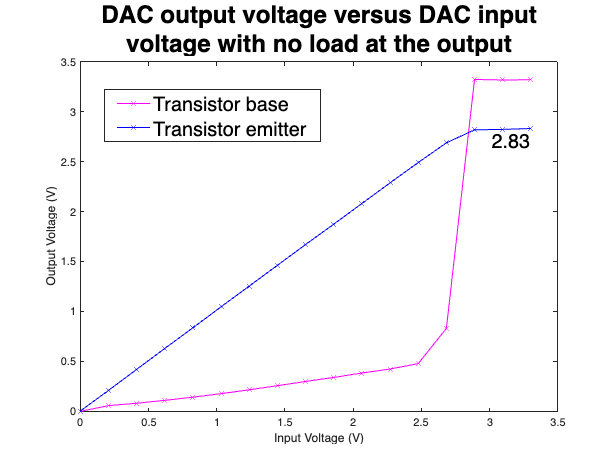

dac_input = [0 0.206451612903226 0.412903225806452 0.619354838709677 0.825806451612903 1.03225806451613 1.23870967741935 1.44516129032258 1.65161290322581 1.85806451612903 2.06451612903226 2.27096774193548 2.47741935483871 2.68387096774194 2.89032258064516 3.09677419354839 3.3];

dac_unbuff_no_load = [0.00029 0.05771 0.08159 0.1104 0.14257 0.17767 0.21611 0.25702 0.29951 0.3399 0.38418 0.42398 0.47831 0.8307 3.3212 3.3161 3.318];
dac_buff_no_load = [0.00384 0.20963 0.42009 0.6297 0.8366 1.0469 1.2543 1.462 1.6696 1.8732 2.0801 2.287 2.4899 2.6869 2.8172 2.8217 2.8304];

dac_unbuff_loaded = [0.00029 0.8202 1.0443 1.2606 1.4713 1.6842 1.8941 2.0981 2.307 2.5125 2.7173 2.9261 3.131 3.2658 3.262 3.252 3.2683];
dac_buff_loaded = [0.00002 0.20509 0.41189 0.6178 0.8227 1.0291 1.2318 1.4325 1.6364 1.8371 2.0325 2.2334 2.4415 2.5491 2.5788 2.579 2.5854];

figure();
plot(dac_input, dac_unbuff_no_load, 'm-x', dac_input, dac_buff_no_load, 'b-x');
xlabel('Input Voltage (V)');
ylabel('Output Voltage (V)');
title(["DAC output voltage versus DAC input", "voltage with no load at the output"], "FontSize", 22);
legend(["Transistor base", "Transistor emitter"], "Position", [0.17 0.7 0.35, 0.1], "FontSize", 18);
text(dac_input(end), dac_buff_no_load(end), sprintf('%.2f', dac_buff_no_load(end)), 'HorizontalAlignment', 'right', 'VerticalAlignment', 'top', 'FontSize', 18);
saveas(gcf, 'Report/Figures/Testing/DAC_no_load.png');

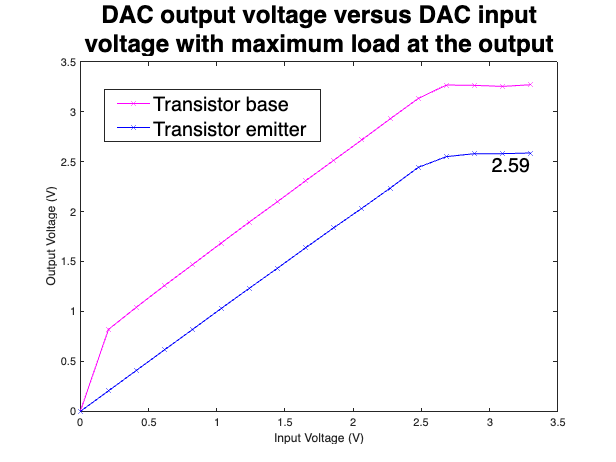


figure();
plot(dac_input, dac_unbuff_loaded, 'm-x', dac_input, dac_buff_loaded, 'b-x');
xlabel('Input Voltage (V)');
ylabel('Output Voltage (V)');
title(["DAC output voltage versus DAC input", "voltage with maximum load at the output"], "FontSize", 22);
legend(["Transistor base", "Transistor emitter"], "Position", [0.17 0.7 0.35, 0.1], "FontSize", 18);
text(dac_input(end), dac_buff_loaded(end), sprintf('%.2f', dac_buff_loaded(end)), 'HorizontalAlignment', 'right', 'VerticalAlignment', 'top', 'FontSize', 18);
saveas(gcf, 'Report/Figures/Testing/DAC_loaded.png');


dac_input = dac_input(1:13);
dac_buff_no_load = dac_buff_no_load(1:13);
dac_buff_loaded = dac_buff_loaded(1:13);

coefficients_no_load = polyfit(dac_input, dac_buff_no_load, 1);
m_no_load = coefficients_no_load(1)

m_no_load = 1.0048

b_no_load = coefficients_no_load(2)

b_no_load = 0.0063

r = corrcoef(dac_input, dac_buff_no_load);
r_2_no_load = r(1,2)^2

r_2_no_load = 1.0000


coefficients_no_load = polyfit(dac_input, dac_buff_loaded, 1);
m_loaded = coefficients_no_load(1)

m_loaded = 0.9837

b_loaded = coefficients_no_load(2)

b_loaded = 0.0070

r = corrcoef(dac_input, dac_buff_loaded);
r_2_loaded = r(1,2)^2

r_2_loaded = 1.0000

ADC range

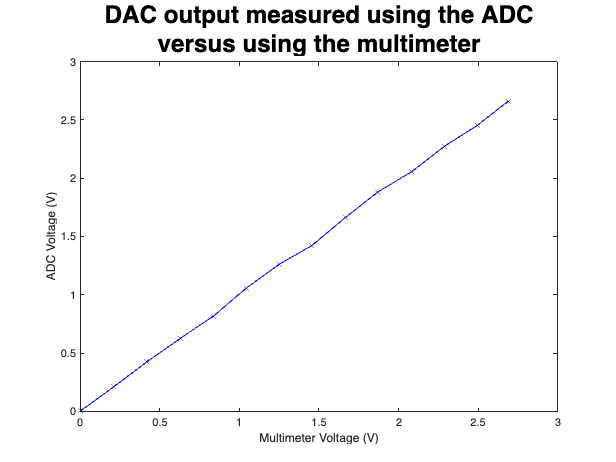

adc_multimeter = [0.00299 0.20852 0.41849 0.6282 0.8363 1.0419 1.2487 1.4556 1.6649 1.8689 2.0821 2.2859 2.4966 2.6888];
adc_bits = [0.00483516483516484 0.20952380952381 0.425494505494506 0.626153846153846 0.817142857142857 1.05648351648352 1.26117216117216 1.42315018315018 1.66168498168498 1.88087912087912 2.05575091575092 2.27172161172161 2.45465201465201 2.66095238095238];

figure();
plot(adc_multimeter, adc_bits, 'b-x');
xlabel('Multimeter Voltage (V)');
ylabel('ADC Voltage (V)');
title(["DAC output measured using the ADC", "versus using the multimeter"], "FontSize", 22);
saveas(gcf, 'Report/Figures/Testing/ADC.png');


coefficients_adc = polyfit(adc_multimeter, adc_bits, 1);
m_adc = coefficients_adc(1)

m_adc = 0.9877

b_adc = coefficients_adc(2)

b_adc = 0.0082

r = corrcoef(adc_multimeter, adc_bits);
r_adc = r(1,2)^2

r_adc = 0.9997

Resistors

R = [0.02 1 1.21 1.52 1.88 2.26 2.68 3.42 3.85 4.84 5.59 6.72 7.49 8.2 9.9];
vr_ave = [1.04 1.95 2.13 2.42 2.7 3.06 3.45 4.09 4.48 5.35 5.96 6.91 7.52 8.09 9.39]/5;
vr_sin = [1.03 1.94 2.11 2.4 2.69 3.04 3.44 4.08 4.47 5.35 5.96 6.91 7.52 8.1 9.4]/5;

r = corrcoef(vr_ave, vr_sin);
r_r = r(1,2)^2

r_r = 1.0000


k = vr_ave * 5/105;
rm = k*100./(1-k);

% curveFitter(R, vr_ave)

r = corrcoef(R, rm);
r_rv = r(1,2)^2

r_rv = 0.9999

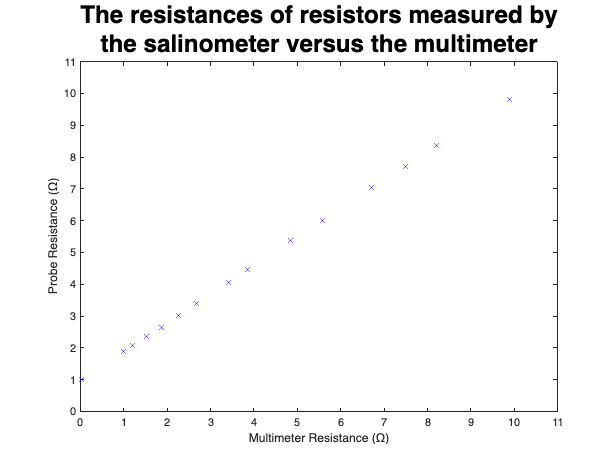


figure();
plot(R, rm, 'bx');
xlabel('Multimeter Resistance (Ω)');

ylabel('Probe Resistance (Ω)');
title(["The resistances of resistors measured by", "the salinometer versus the multimeter"], "FontSize", 22);
xlim([0,11])
ylim([0,11])
saveas(gcf, 'Report/Figures/Testing/R_uncorrected.png');

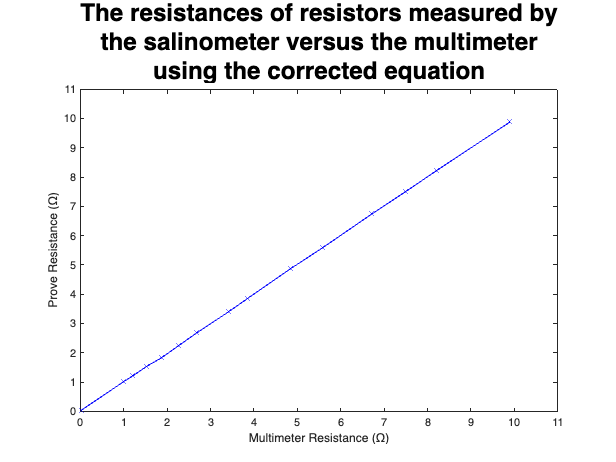


% (p1*x + p2)/(x + q1)
P1 = 17.4687;
P2 = 18.4643;
Q1 = 91.8315;

r_corr = (P2 - Q1 * vr_ave)./(vr_ave - P1);

figure();
plot(R, r_corr, 'b-x');
xlabel('Multimeter Resistance (Ω)');
ylabel('Prove Resistance (Ω)');
title(["The resistances of resistors measured by", "the salinometer versus the multimeter", "using the corrected equation"], "FontSize", 22);
xlim([0,11])
ylim([0,11])
saveas(gcf, 'Report/Figures/Testing/R_corrected.png');


coefficients_r = polyfit(R, r_corr, 1);
m_r = coefficients_r(1)

m_r = 1.0000

b_r = coefficients_r(2)

b_r = 8.4802e-05


r = corrcoef(R, r_corr);
r_r_corr = r(1,2)^2

r_r_corr = 1.0000

Resistance mapping eqn

syms vr R alpha beta K
eqn = vr == (R + alpha)/(R + beta) * K;
solve(eqn, R)

$$ans = -\frac{K\,\alpha -\beta \,\mathrm{vr}}{K-\mathrm{vr}}$$

syms y x p1 p2 q1
eqn2 = y == (p1*x + p2)/(x + q1);
solve(eqn2, x)

$$ans = -\frac{p_{2}-q_{1}\,y}{p_{1}-y}$$